# Homework 1.1

## Create a state-space model

The state-space model is:

    x_{t+1} = 0.95 * x_t + N(0, 0.05)

    y_t = 2.6 * x_t + N(0, 0.01)

clearvars;
s = ssmodel(0.0, 0.05, 0.01, 0.95, 1.0, 2.6, 1.0);

## Simulation

For 1000 times.

T = 1000;
xk = zeros([T+1,1]); % including t=0
yk = zeros([T+1,1]);
yk(1) = s.get_y;
xk(1) = s.get_xt;
for t = 1:T
    xk(t+1) = s.forward;
    yk(t+1) = s.get_y;
end

## Plot results

Show x_k and y_k.

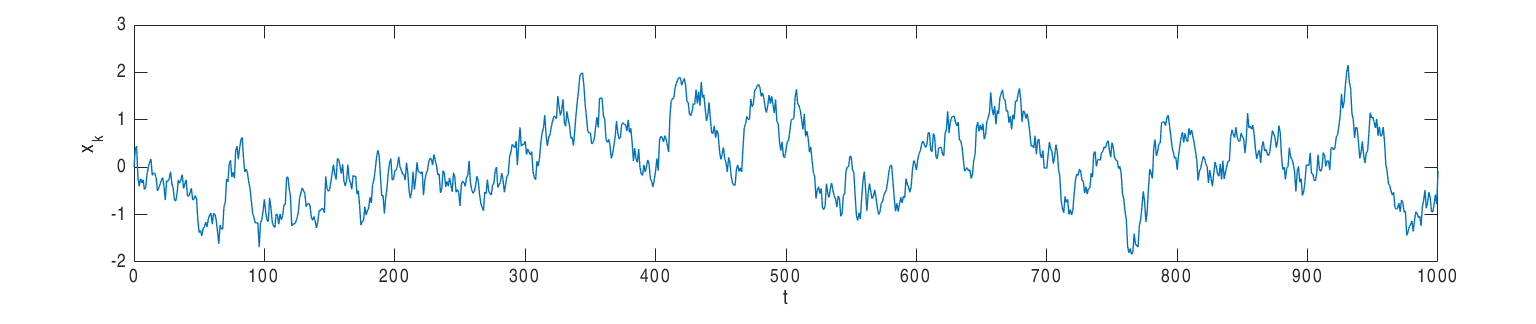

configs.LineWidth=1.0;
figure,plot(0:T, xk, configs), ylabel('x_k'), xlabel('t');
tight_layout([0.8, 0.3], 14);

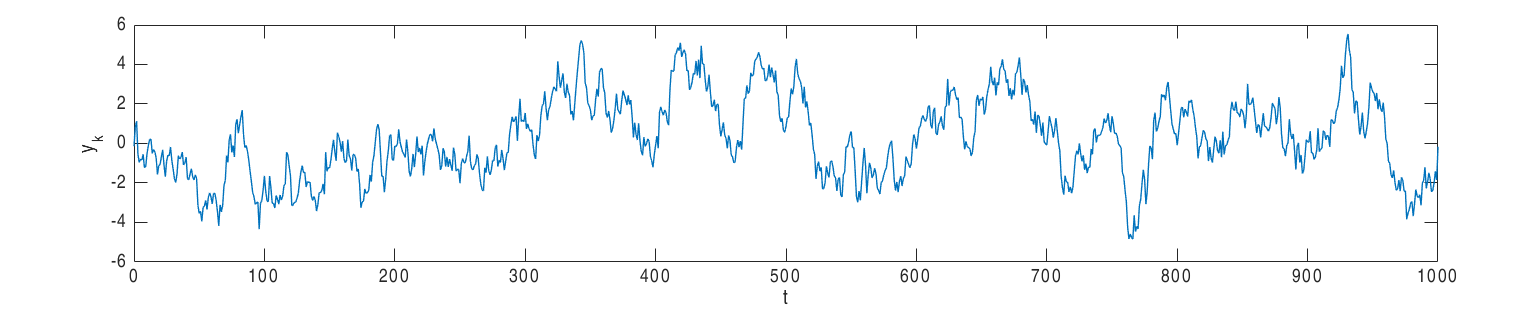

figure,plot(0:T, yk, configs), ylabel('y_k'), xlabel('t');
tight_layout([0.8, 0.3], 14);

# Homework 1.3

## Calculate and show variances

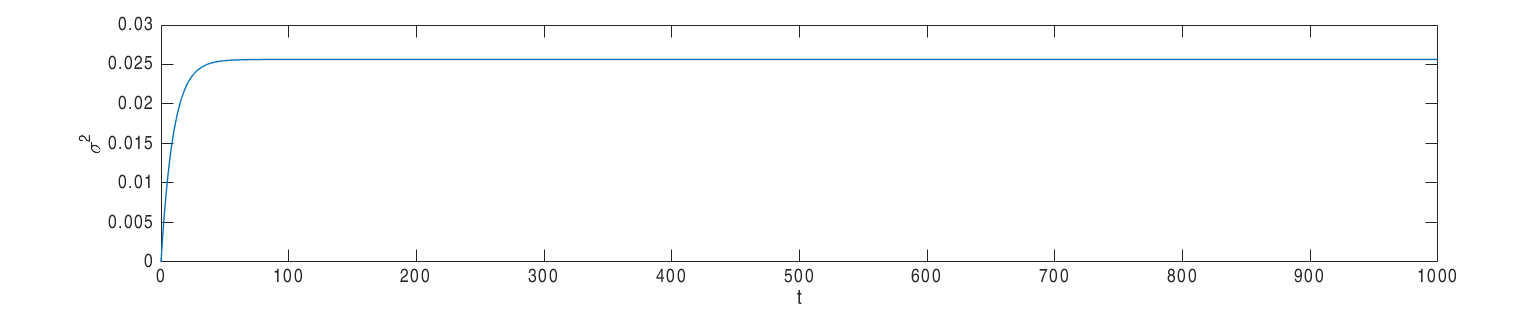

% Know nothing.
v = [0.0; zeros([T,1])];
for i = 1:T
    v(i+1) = (s.A.^2)*v(i) + (s.B.^2)*s.epsilon.^2;
end
figure,plot(0:T, v, configs), ylabel('\sigma^2'), xlabel('t');
tight_layout([0.8, 0.3], 14);

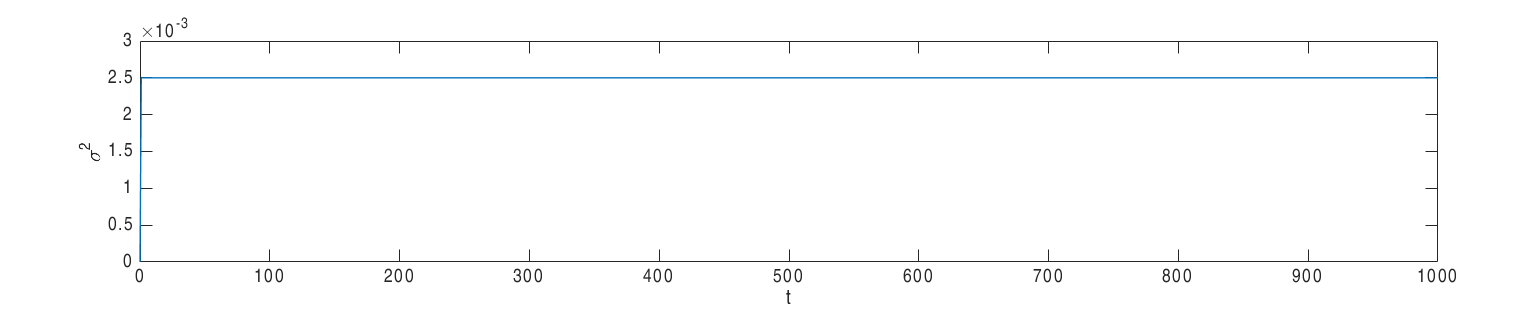

% Knowing all truth.
v = [0.0; (s.epsilon.^2)*ones(T,1)];
figure,plot(0:T, v, configs), ylabel('\sigma^2'), xlabel('t');
tight_layout([0.8, 0.3], 14);

## Calculate SS estimation

with the default configurations.

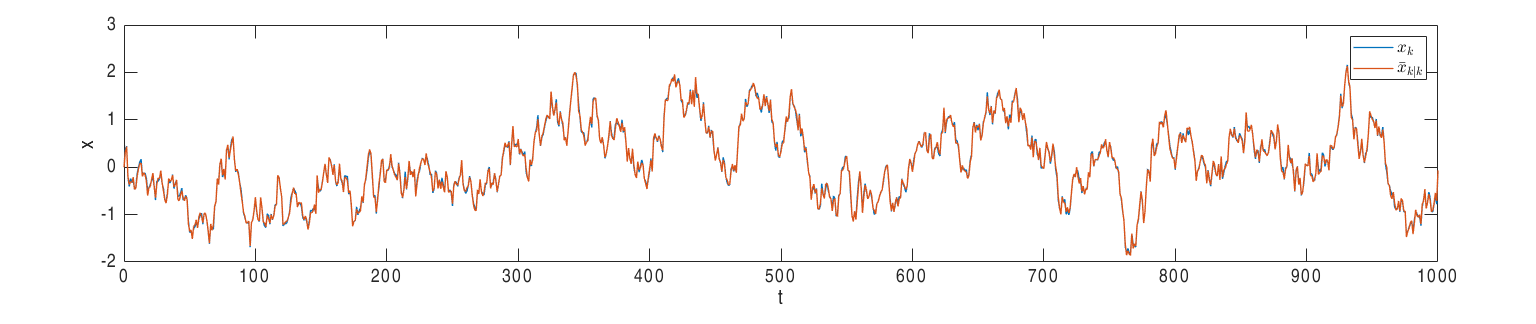

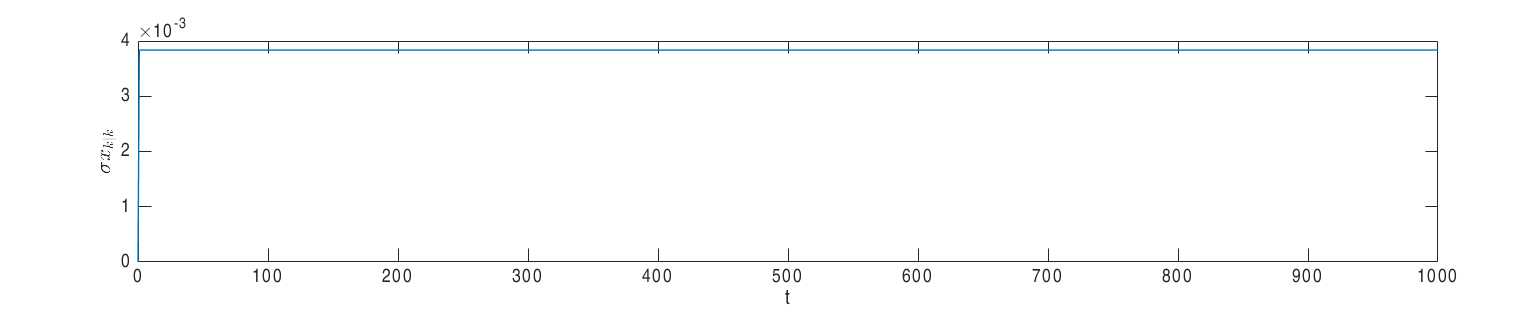

show_ss_estimation(T, s, xk, yk);

# Homework 1.4

## Calculate SS estimation with a wrong noise

The std. of the epsilon value is assumed to be 0.005 instead of the true value (0.05).

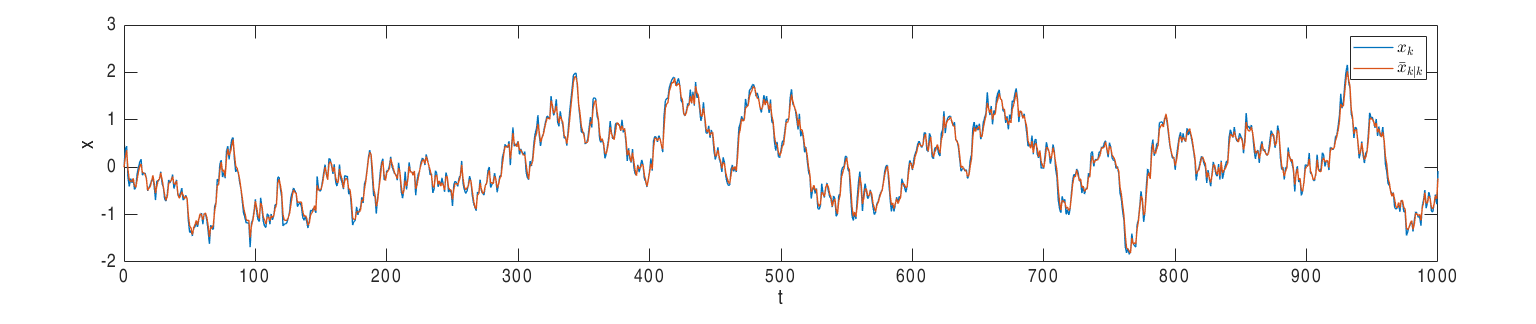

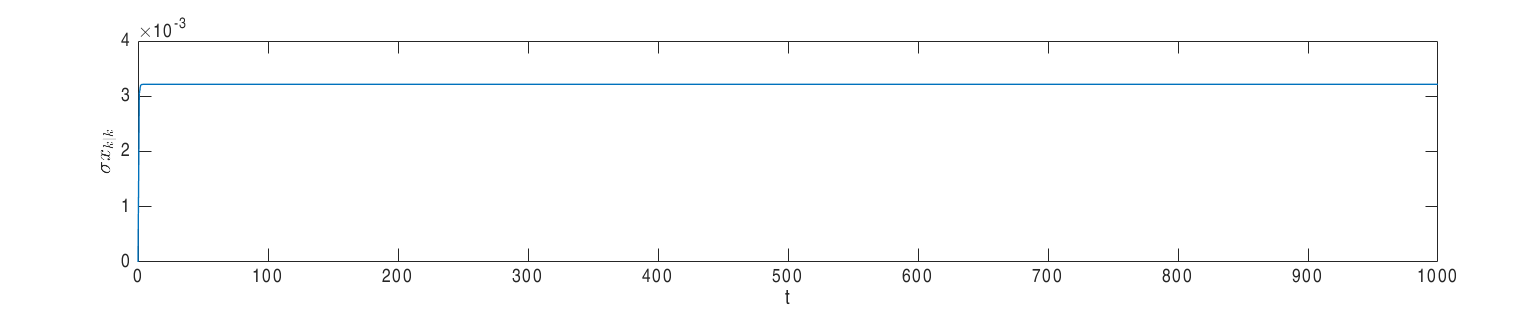

s_wrong = s.copy();
s_wrong.epsilon = 0.005;
xkk_1 = show_ss_estimation(T, s_wrong, xk, yk);

# Homework 1.5

## Calculate SS estimation with a wrong model

The output y is modeling with a wrong equation y_k = 2.1 x_k + N(nu).

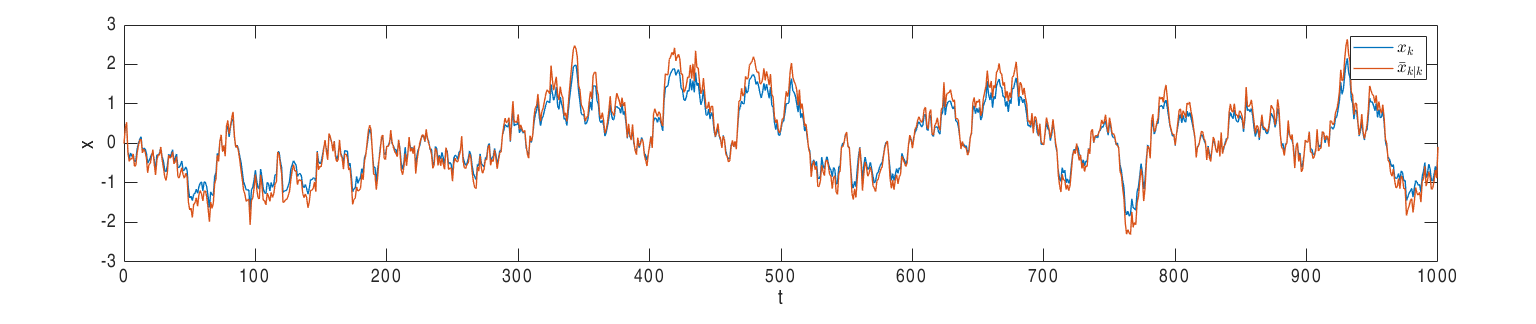

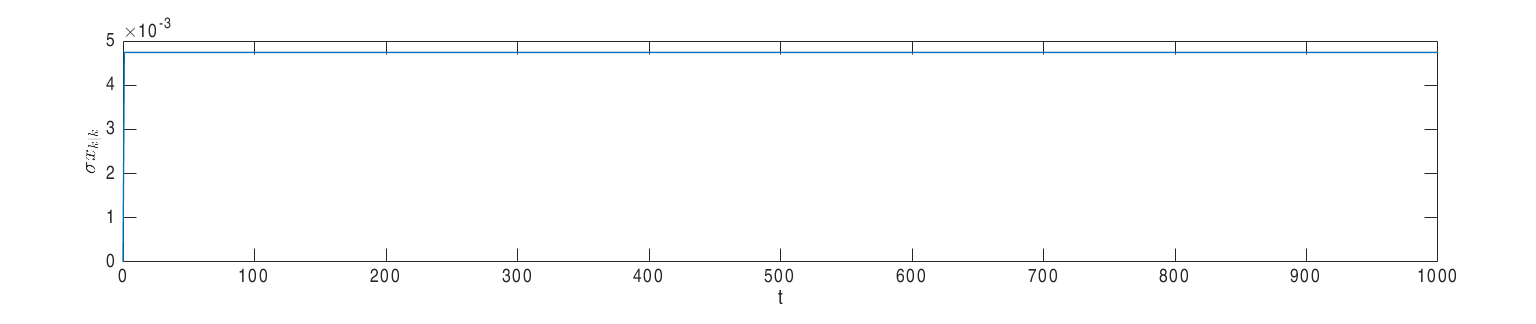

s_wrong = s.copy();
s_wrong.C = 2.1;
xkk_2 = show_ss_estimation(T, s_wrong, xk, yk);

# Homework 1.6

## Calculate RMSE

disp(['RMSE, wrong epsilon: ', num2str(rmse(xk, xkk_1))]);

RMSE, wrong epsilon: 0.077722


disp(['RMSE, wrong model:   ', num2str(rmse(xk, xkk_2))]);

RMSE, wrong model:   0.19012


# Functions

## State-space estimation

show the ss estimation of a time series of known measurements.

- T: iteration number.

- s: SS handle.

- xk: vector, the record of the states.

- yk: vector, the record of the measurements.

function xkk = show_ss_estimation(T, s, xk, yk)
% Calculate the estimation.
xkk = zeros([T+1,1]);
skk = zeros([T+1,1]);
xkk(1) = xk(1);
skk(1) = 0.0;
for t = 1:T
    [res1, res2] = s.estimate(xkk(t), skk(t), yk(t+1));
    xkk(t+1) = res1;
    skk(t+1) = res2;
end
skk = sqrt(skk);

% Show results.
configs.LineWidth=1.0;
figure,plot(0:T, [xk, xkk], configs);
legend({'$x_k$', '$\bar{x}_{k|k}$'},'Interpreter','latex')
ylabel('x'), xlabel('t');
tight_layout([0.8, 0.3], 14);
figure,plot(0:T, skk, configs);
ylabel('$\sigma{x}_{k|k}$','Interpreter','latex'), xlabel('t');
tight_layout([0.8, 0.3], 14);
end

## RMSE

Calculate the RMSE between two vectors: v1, v2

function value = rmse(v1, v2)
    value = sqrt(mean((v1 - v2).^2,'all'));
end